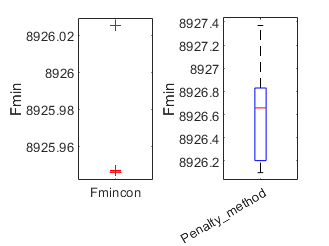

%优化结果对比
figure
subplot(1,2,1);
boxplot(result_fmin_f(1:9,5),'Labels',{'Fmincon'});
ylabel("Fmin");
subplot(1,2,2);
boxplot(result_fmin_p(:,5),"Labels",{'Penalty_method'});
ylabel('Fmin');

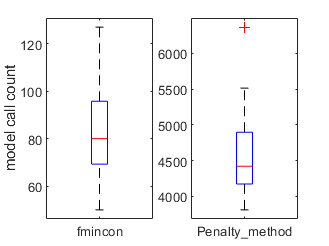


%模型调用次数
figure
subplot(1,2,1);
boxplot(result_fmin_f(1:9,6),"Labels",{'fmincon'});
ylabel('model call count');
subplot(1,2,2);
boxplot(result_fmin_p(:,6),"Labels",{'Penalty_method'});

data1=[result_fmin_f(1:9,5:6)];
data2=[result_fmin_p(:,5:6)];
data_process=[min(data1),min(data2);mean(data1),mean(data2);max(data1),max(data2);median(data1),median(data2)];